**This is an example of how to create a 3D scatter plot in MATLAB®**.

You can open this example in the [Live Editor](https://www.mathworks.com/products/matlab/live-editor.html) with MATLAB version 2016a or higher.

Read about the [`scatter3`](http://www.mathworks.com/help/matlab/ref/scatter3.html) function in the MATLAB documentation. For more examples, go to [MATLAB Plot Gallery](http://www.mathworks.com/discovery/gallery.html)

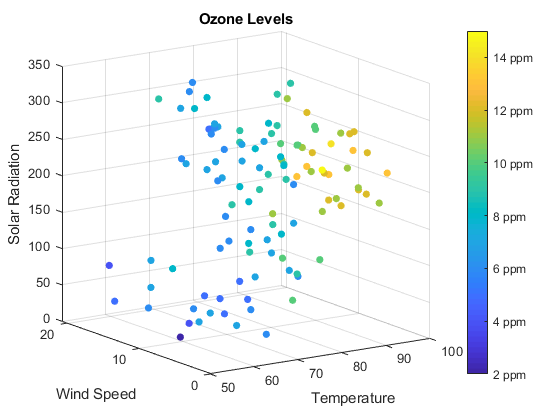

% Load data on ozone levels
load ozoneData Ozone Temperature WindSpeed SolarRadiation

% Calculate the ozone levels
z = (Ozone).^(1/3);
response = z;

% Make a color index for the ozone levels
nc = 16;
offset = 1;
c = response - min(response);
c = round((nc-1-2*offset)*c/max(c)+1+offset);

% Create a 3D scatter plot using the scatter3 function
figure
scatter3(Temperature, WindSpeed, SolarRadiation, 30, c, 'filled')
view(-34, 14)

% Add title and axis labels
title('Ozone Levels')
xlabel('Temperature')
ylabel('Wind Speed')
zlabel('Solar Radiation')

% Add a colorbar with tick labels
colorbar('Location', 'EastOutside', 'YTickLabel',...
    {'2 ppm', '4 ppm', '6 ppm', '8 ppm', ...
     '10 ppm', '12 ppm', '14 ppm'})

*Copyright 2012-2018 The MathWorks, Inc.*